%ProcessGnssMeasScript.m, script to read GnssLogger output, compute and plot:
% pseudoranges, C/No, and weighted least squares PVT solution
%
% you can run the data in pseudoranges log files provided for you: 
% prFileName = 'gnss_log_2020_08_07_15_09_27.txt'; %with duty cycling, no carrier phase
close all;
clear all;
prFileName = 'gnss_log_2020_08_07_03_36_36.txt'; %no duty cycling, with carrier phase
% as follows
% 1) copy everything from GitHub google/gps-me     asurement-tools/ to 
%    a local directory on your machine
% 2) change 'dirName = ...' to match the local directory you are using:

% dirName = 'E:\Users\ASUS\Documents\Lab Research\Submit\NewCode\gps-measurement-tools-master\opensource\demoFiles';
% dirName = 'E:\Users\ASUS\Documents\Lab Research\Submit\NewCode\gps-measurement-tools-master\opensource\demoFiles';
dirName = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\1';
% dirName='E:\Users\ASUS\Desktop\TEST\mi8';
% 3) run ProcessGnssMeasScript.m script file 
param.llaTrueDegDegM = [];

%Author: Frank van Diggelen
%Open Source code for processing Android GNSS Measurements

%% data
%To add your own data:
% save data from GnssLogger App, and edit dirName and prFileName appropriately
%dirName = 'put the full path for your directory here';
%prFileName = 'put the pseuoranges log file name here';


%% parameters
%param.llaTrueDegDegM = [];
%enter true WGS84 lla, if you know it:
% param.llaTrueDegDegM = [37.422578, -122.081678, -28];%Charleston Park Test Site

%% Set the data filter and Read log file
dataFilter = SetDataFilter;
[gnssRaw,gnssAnalysis] = ReadGnssLogger(dirName,prFileName,dataFilter);


Reading file ..\TEST\Room_810_PCL_0804\Test0_5Hz\1/gnss_log_2020_08_07_03_36_36.txt


if isempty(gnssRaw), return, end

%% Get online ephemeris from Nasa ftp, first compute UTC Time from gnssRaw:
fctSeconds = 1e-3*double(gnssRaw.allRxMillis(end));
utcTime = Gps2Utc([],fctSeconds);
allGpsEph = GetNasaHourlyEphemeris(utcTime,dirName);

Reading GPS ephemeris from 'hour2190.20n' file in local directory
..\TEST\Room_810_PCL_0804\Test0_5Hz\1\


if isempty(allGpsEph), return, end

%% process raw measurements, compute pseudoranges:
% [gnssMeas] = ProcessGnssMeas(gnssRaw);% 杩欎竴姝ヨ皟鏁存垚鎴戜滑鐨勭畻娉曪紝鍘熸湁瀛楁鍒嗚鎴愪袱閮ㄥ垎瀛楁
 [gnssMeas]= ProcessGnssMeasForBackscatter(gnssRaw);


Removed 7 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s


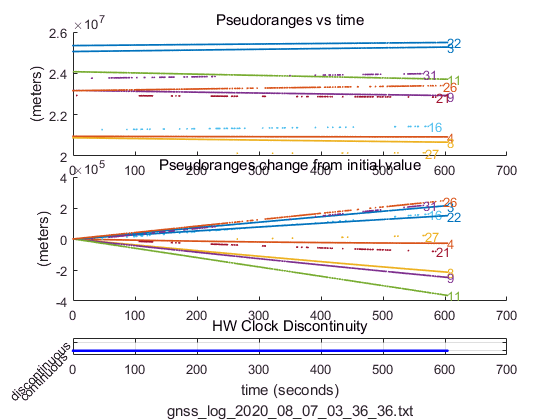

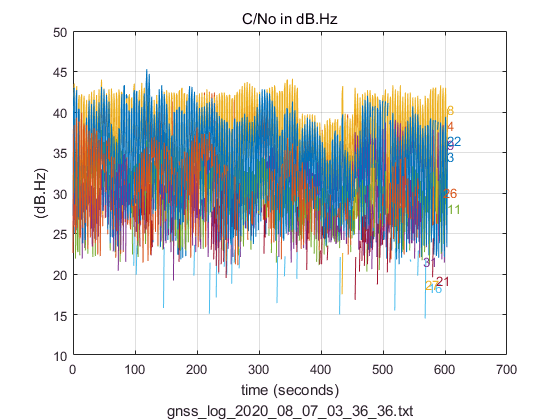

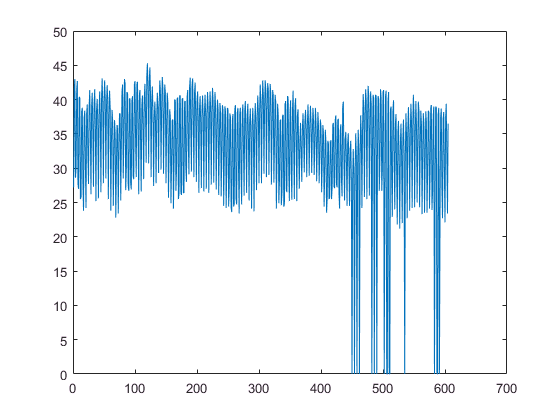

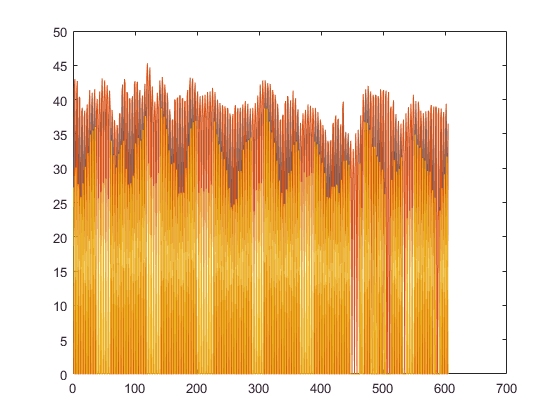

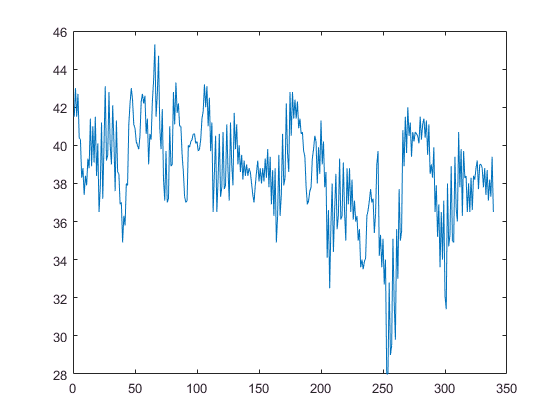

 
 [gnssMeasBackscattered]=Seprate(gnssMeas,prFileName);

 
% [gnssMeasBackscattered]=gnssMeasSeprate(gnssMeas,prFileName);
% %% plot pseudoranges and pseudorange rates
% h1 = figure;
% [colors] = PlotPseudoranges(gnssMeas,prFileName);
% h2 = figure;
% PlotPseudorangeRates(gnssMeas,prFileName,colors);
% h3 = figure;
% PlotCno(gnssMeas,prFileName,colors);

%% compute WLS position and velocity
gpsPvt = GpsWlsPvt(gnssMeasBackscattered,allGpsEph);
% gpsPvt= GpsWlsPvtBackscatter(gnssMeas,allGpsEph);%

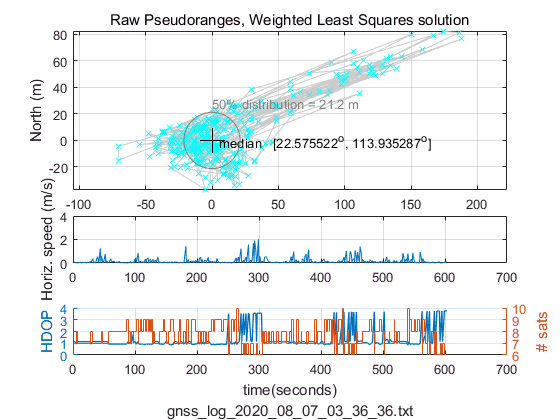

Median llaDegDegM = [22.5755220 113.9352871 152.24]


%% plot Pvt results
h4 = figure;
ts = 'Raw Pseudoranges, Weighted Least Squares solution';
PlotPvt(gpsPvt,prFileName,param.llaTrueDegDegM,ts); drawnow;

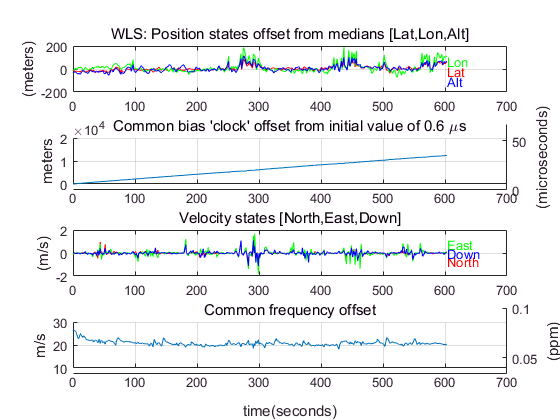

h5 = figure;
PlotPvtStates(gpsPvt,prFileName);

%% Plot Accumulated Delta Range 
if any(any(isfinite(gnssMeas.AdrM) & gnssMeas.AdrM~=0))
    [gnssMeas]= ProcessAdr(gnssMeas);
    h6 = figure;
    PlotAdr(gnssMeas,prFileName,colors);
    [adrResid]= GpsAdrResiduals(gnssMeas,allGpsEph,param.llaTrueDegDegM);drawnow
    h7 = figure;
    PlotAdrResids(adrResid,gnssMeas,prFileName,colors);
end

## 距离和误差计算

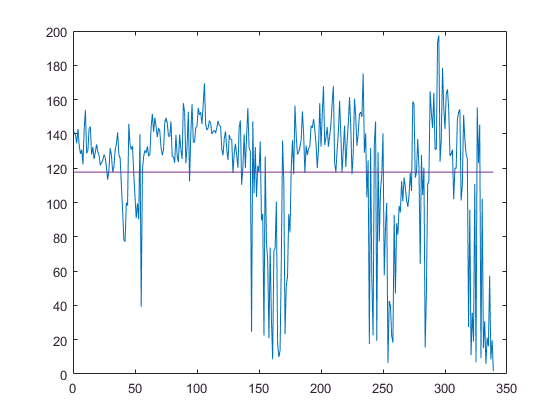

b=[22.576062252004220   113.9363809520042;];
% distance=distanceCountViaCoordinate(gpsPvt.allLlaDegDegM(:,1:2),b)
lenBackscatted = length(gpsPvt.allLlaDegDegM(:,1));
distance = zeros(lenBackscatted,1);
for i = 1:length(gpsPvt.allLlaDegDegM(:,1))
    distance(i)=distanceCountViaCoordinate(gpsPvt.allLlaDegDegM(i,1:2),b);
end

disAver = mean(distance(:)) * ones(lenBackscatted);

figure
plot(distance)
hold on
plot(disAver)